# Plot Gas Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

countries = readmatrix("./data/gPrices.xlsx", "Sheet", "countries", "OutputType", "string");
prices = readmatrix("./data/gPrices.xlsx", "Sheet", "prices");
ctry = "Germany";
% Find the index value for ctry
idx = strcmp(ctry, countries);
ctryPrices = prices(:, idx);

## Task 1 

A common way to develop `for` loops is to first write the code body for a specific value of the looping variable. Then once you know your code works, add the loop.

Here, the starter code creates the trend line for gas prices in Germany and the first country in `countries` (`k``=``1`). The code works, so your task will be to replace `k``=``1` with a `for` loop that loops through all of the countries in `countries`.

for k = 1:length(countries)
    c(k, :) = polyfit(ctryPrices, prices(:, k), 1);
end

Plot linear fit.

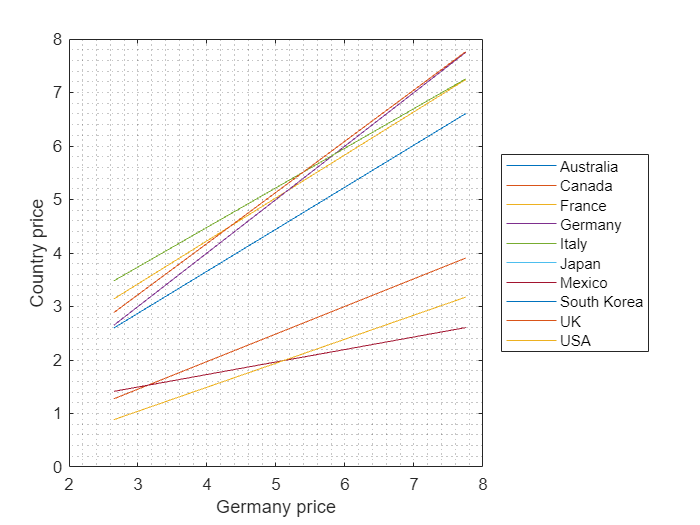

linfit = ctryPrices.*c(:, 1)' + c(:, 2)';
plot(ctryPrices, linfit)
grid minor
legend(countries, "Location", "eastoutside")
xlabel(ctry + " price")
ylabel("Country price")